% Cleanup!
clear all 
close all
clc

[MotionData]=ParseMatlabApp('10min_control_50hz.mat')

MotionData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [31900×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


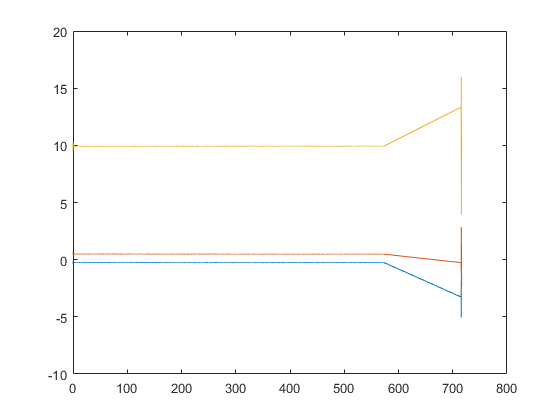

plot(MotionData.t_Accel, MotionData.Accel)



[chunked_t_Accel,chunked_Accel] = TrimMotionData(MotionData,100,0)

Fs = 55.5556

N = 31900

chunk_sz = 100

chunks = 10

chunk_sz_index = 5556

front_trim = 0

index_front = 1

MotionData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [31900×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t_Accel = 1×15 cell array
    {5556×1 double}    {0×0 double}    {5556×1 double}    {0×0 double}    {0×0 double}    {5556×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {5556×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {5556×1 double}


chunked_Accel = 1×15 cell array
    {5556×3 double}    {0×0 double}    {5556×3 double}    {0×0 double}    {0×0 double}    {5556×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {5556×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {5556×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(chunked_t_Accel{1})

N = 5556

Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

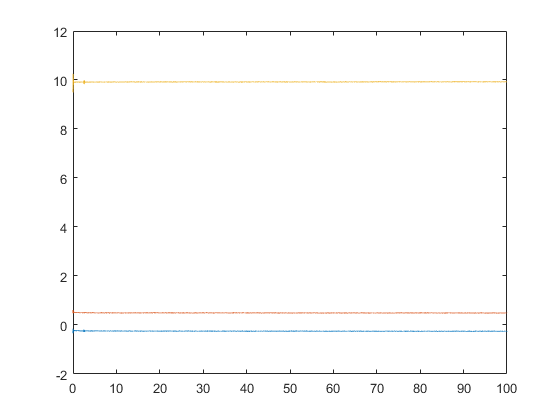

plot(chunked_t_Accel{1}, chunked_Accel{1})

data = chunked_Accel{1}

data =    -0.2387    0.4800    9.4927
   -0.3345    0.6121    9.6499
   -0.1587    0.4752   10.2494
   -0.2375    0.5100    9.8589
   -0.2459    0.5474    9.8134
   -0.2219    0.4944   10.0006
   -0.2315    0.5339    9.9155
   -0.2303    0.5243    9.8937
   -0.2291    0.4908    9.9215
   -0.2291    0.5303    9.9071


y_fft = fft(data(:, 3));
y_fft_shift = abs(fftshift(y_fft));
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

breath_low = 8/60

breath_low = 0.1333

breath_high = 20/60

breath_high = 0.3333

hb_low = 40/60

hb_low = 0.6667

hb_high = 100/60

hb_high = 1.6667


filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/10;

filter_inds = find(frequencies_shifted == 0)

filter_inds = 2779

y_fft_shift(filter_inds) = 0

y_fft_shift =     0.0582
    0.0471
    0.0787
    0.0246
    0.0157
    0.0943
    0.0592
    0.0927
    0.0079
    0.0645


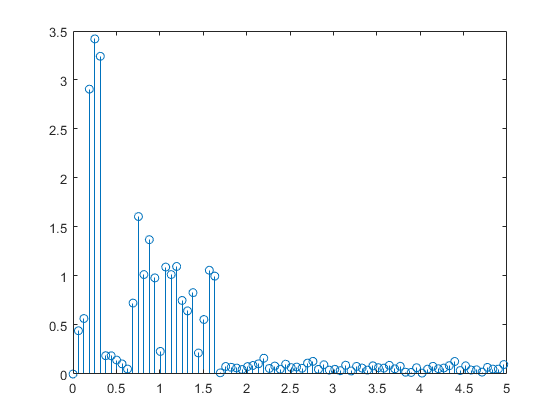


figure(2)
stem(frequencies_shifted, y_fft_shift)
xlim([0 5])